# Pre set up

clear all;
close all;
clc;


## Attempting online measure

% device_list = mobiledevlist();
% disp(device_list);
% m = mobiledev('Samsung Galaxy Tab S7 FE');
% 
% % Configure Sensors
% m.AngularVelocitySensorEnabled = 1;
% 
% % sampling rate
% m.SampleRate = 100; % [Hz]
% 
% % 1 - Start Data Logging
% disp('Logging started');
% m.Logging = 1; 
% 
% capture_duration_seconds = 60; % in seconds
% pause(capture_duration_seconds);
% 
% % 2 - Stop Logging
% m.Logging = 0;
% disp('Logging stopped');
% 
% % Retrieve angular velocity (x, y, z) in [rad/s] and time (t) in [s]
% [omega, t] = angvellog(m);
% 
% % 3 - Save the raw data 
% filename = 'gyro_raw_data_test_1.mat';
% save(filename, 'omega', 't');
% disp('Data successfully saved to %s\n', filename);

# Load data

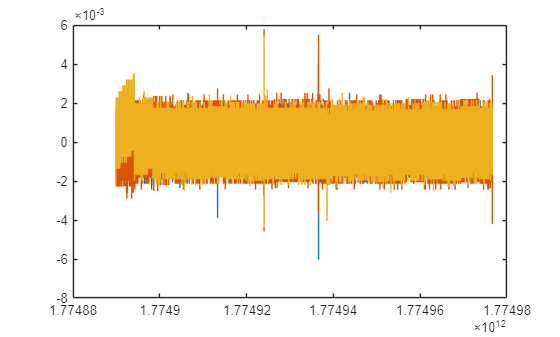

data = load("sensorlog_angvel_20260330_165739.mat");

table = data.sensorlog_angvel_20260330_165739;
table_angular_velocity = [table.X, table.Y, table.Z];

% Define our sampling frequency
Fs = 100; % [Hz], frequency of matlab mobile sampling

% Visualization pre elaboration
figure(1);
plot(table.timestamp, table_angular_velocity);

length(table.timestamp)

ans = 9046141

## Filtering

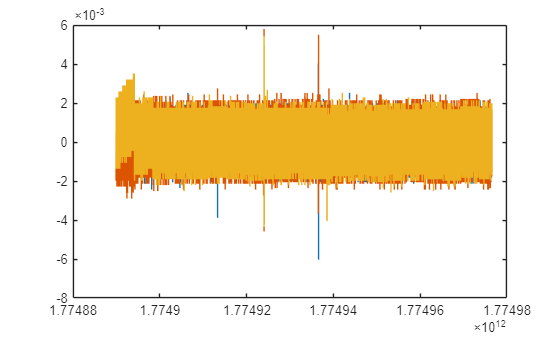

% Crop initial data and last data
index = 6000; % [100 hz so 6000 is first 60 seconds]
start_index = index;
end_index = height(table) - index;

% Create a new trimmed table
table_trimmed = table(start_index:end_index, :);
table_angular_velocity_trimmed = [table_trimmed.X, table_trimmed.Y, table_trimmed.Z];

% Plot the new data
figure(2);
plot(table_trimmed.timestamp, table_angular_velocity_trimmed);

length(table_trimmed.timestamp)

ans = 9034142

## Consider non-stationary measurements

% Calculate the magnitude of angular velocity 
omega_mag = sqrt(table_trimmed.X.^2 + table_trimmed.Y.^2 + table_trimmed.Z.^2);

% Threhsold for magnitute check
threshold = 0.01;

% Find indices where threshold is exceeded
keep_indices = omega_mag < threshold;

% Print the number of such indices
count = sum(~keep_indices)

count = 0


% Eliminate such values
table_trimmed = table_trimmed(keep_indices, :);

% Consider remaining table
table_angular_velocity_trimmed = [table_trimmed.X, table_trimmed.Y, table_trimmed.Z];
omega = table_angular_velocity_trimmed(:, 1); % Using X-axis for Allan Var



## Model:


$$\Omega \left(t\right)=\Omega_{\textrm{ideal}} \left(t\right)+\textrm{ARW}\left(t\right)+\textrm{RRW}\left(t\right)+\textrm{BI}\left(t\right)$$


Where:

- $\Omega_{\textrm{ideal}}$ is the ideal real value

- $\textrm{ARW}$ is the Angle Random Walk

- $\textrm{RRW}$ is the Rate Random Walk

- $\textrm{BI}$ is the BIas Instability

## Allan Variance Calculation

We consider only the x axis for simplicity

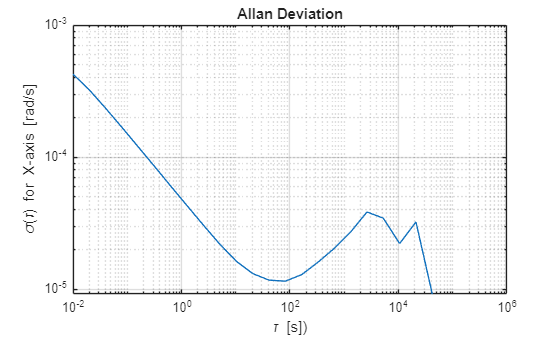

[allan_var, tau] = allanvar(omega, 'octave', Fs);
allan_dev = sqrt(allan_var);

%% Plot
figure(1);
loglog(tau, allan_dev); 
grid on;
title('Allan Deviation');
xlabel('\tau [s])');
ylabel('\sigma(\tau) for X-axis [rad/s]');

## Angle random walk

We can model:


$$\sigma {\;}^2 \left(\tau \;\right)=\frac{N^2 }{\tau \;}$$


Therefore in a log-log plot with $\sigma \left(\tau \right)$versus $\tau \;$we would have a line with a slope of $-\frac{1}{2}$, namely:


$$\log \left(\sigma \;\right)=-\frac{1}{2}\log \left(\tau \;\right)+\log \left(N\right)$$


So the value of $N$ can be read at $\tau =1$

slope = -1/2;
log_tau = log10(tau);
log_allan_dev = log10(allan_dev);
dlog_allan_dev = diff(log_allan_dev) ./ diff(log_tau);
[~, i] = min(abs(dlog_allan_dev - slope));

% Find the intercept of the line.
b = log_allan_dev(i) - slope*log_tau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 4.8055e-05

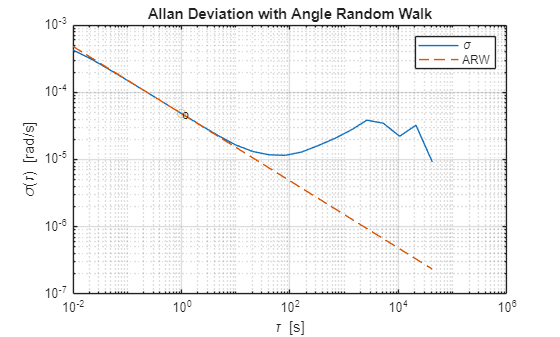



% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);

figure(2)
loglog(tau, allan_dev, tau, lineN, '--', tauN, N, 'o')
title('Allan Deviation with Angle Random Walk')
xlabel('\tau [s]')
ylabel('\sigma(\tau) [rad/s]')
legend('\sigma', 'ARW')
text(tauN, N, 'o')
grid on

## Rate random walk

We can model:


$$\sigma {\;}^2 \left(\tau \;\right)=\frac{K^2 \tau \;}{3}\;$$


Therefore in a log-log plot with $\sigma \left(\tau \right)$versus $\tau \;$we would have a line with a slope of $\frac{1}{2}$, meaning :


$$\log \left(\sigma \;\right)=\frac{1}{2}\log \left(\tau \;\right)+\log \left(K\right)-\frac{1}{2}\log \left(3\right)$$


We can determine the value of $K$at $\tau =3$because clearly the above equation simplifies to


$$\log \left(\sigma \;\right)=\log \left(K\;\right)$$


% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 1/2;
logtau = log10(tau);
log_allan_dev = log10(allan_dev);
dlog_allan_dev = diff(log_allan_dev) ./ diff(log_tau);
[~, i] = min(abs(dlog_allan_dev - slope));

% Find the intercept of the line.
b = log_allan_dev(i) - slope*log_tau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
K = 10^logK

K = 1.2999e-06

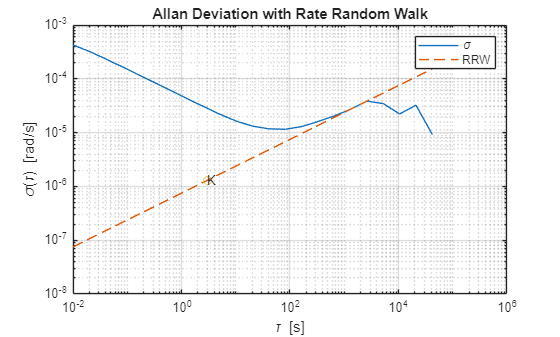


% Plot the results.
tauK = 3;
lineK = K .* sqrt(tau/3);

figure(3);
loglog(tau, allan_dev, tau, lineK, '--', tauK, K, 'o')
title('Allan Deviation with Rate Random Walk')
xlabel('\tau [s]')
ylabel('\sigma(\tau) [rad/s]')
legend('\sigma', 'RRW')
text(tauK, K, 'K')
grid on

## Bias Instability

We can model:


$$\sigma^2 \left(\tau \;\right)={\frac{2B}{\pi \;}}^2 \ln \left(2\right)$$


Therefore in a log-log plot with $\sigma \left(\tau \right)$versus $\tau \;$we would have a line with a slope of $0$, meaning:


$$\log \left(\sigma \;\right)=\frac{1}{2}\log \left({\frac{2B}{\pi \;}}^2 \ln \left(2\right)\right)$$


The value of $B$ can be read off of this line with a scaling of $\sqrt{\;\left(2\frac{\ln \left(2\right)}{\pi \;}\right)}\approx 0\ldotp 664$

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0;
log_tau = log10(tau);
log_allan_dev = log10(allan_dev);
dlog_allan_dev = diff(log_allan_dev) ./ diff(log_tau);
[~, i] = min(abs(dlog_allan_dev - slope));

% Find the y-intercept of the line.
b = log_allan_dev(i) - slope*log_tau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 1.7690e-05

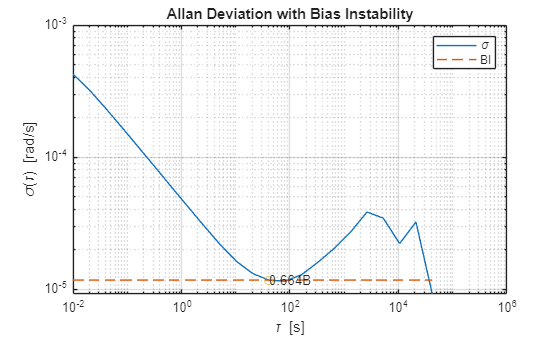


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure(4);
loglog(tau, allan_dev, tau, lineB, '--', tauB, scfB*B, 'o')
title('Allan Deviation with Bias Instability')
xlabel('\tau [s]')
ylabel('\sigma(\tau) [rad/s]')
legend('\sigma', 'BI')
text(tauB, scfB*B, '0.664B')
grid on

## Gyroscope simulation

% Set the gyroscope parameters to the noise parameters determined
% above. Use single-sided noise to match the parameter scaling and 500
% poles for the bias instability model to match the hardware output.
numpoles = 500;
gyro = gyroparams(  'NoiseDensity', N, ...
                    'RandomWalk', K, ...
                    'BiasInstability', B, ...
                    'NoiseType', 'single-sided', ...
                    'BiasInstabilityCoefficients', fractalcoef(numpoles));

% Create the IMU Sensor object
imu = imuSensor('accel-gyro', 'SampleRate', Fs);
imu.Gyroscope = gyro;

% Run the simulation 
% vectors of zeros are the real values
numSamples = size(omega, 1);
accel_ground_truth = zeros(numSamples, 3); % m/s^2
gyro_ground_truth  = zeros(numSamples, 3); % rad/s

% Generate simulated readings
[~, gyro_readings] = imu(accel_ground_truth, gyro_ground_truth);


## Plot comparison simulated vs real

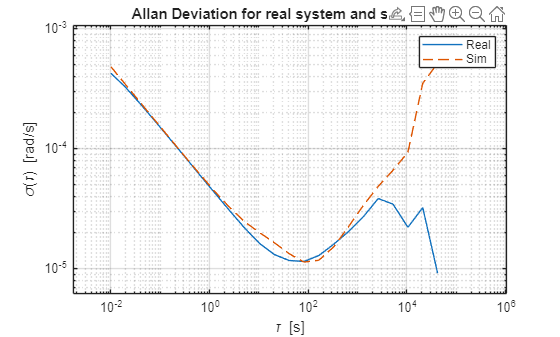

omega_sim = gyro_readings(:, 1);
[allan_var_sim, tau_sim] = allanvar(omega_sim, 'octave', Fs);

allan_dev_sim = sqrt(allan_var_sim);
allan_dev_sim = mean(allan_dev_sim, 2); % Use the mean of the simulations.

figure(5);
loglog(tau, allan_dev, tau_sim, allan_dev_sim, '--')
title('Allan Deviation for real system and simulated')
xlabel('\tau [s]');
ylabel('\sigma(\tau) [rad/s]')
legend('Real', 'Sim')
grid on

## Kalman filter

N is Angle Random Walk (ARW)

K is Rate Random Walk (RRW)

Our model is:

$b_k =b_{k-1} +n{\;}_{k-1\;}$ where $n_{k-1\;} \sim \mathcal{N}\left(0,Q_{\left.k\right)} \right)$

$y_k =b_k +v_k$ where $v_{k\;} \sim \mathcal{N}\left(0,R_k \right)$

Where:

$b_k$ is the bias at time k

And we model the bias as something that drifts over time so we use random walk model with noise $\omega_{k-1}$

We are stationary so what we measure is:


$$y_k =\Omega_{\textrm{ideal}} +b_k +v_k =b_k +v_k$$


Since we are stationary ${\Omega \;\;}_{\textrm{ideal}} =0$

$v_k$ is the measurement noise

Our initial model was


$$\Omega \left(t\right)=\Omega_{\textrm{ideal}} \left(t\right)+\textrm{ARW}\left(t\right)+\textrm{RRW}\left(t\right)+\textrm{BI}\left(t\right)$$


We ignore Bias Instability component for simplicity and we consider stationary situation so we have $\Omega {\;}_{\textrm{ideal}} \left(t\right)=0$

Therefore the model is:


$$\Omega \left(t\right)=\textrm{ARW}\left(t\right)+\textrm{RRW}\left(t\right)$$


Where according to [REFERENCE IEEE 952-1997]:

1) ARW has power spectral desnity $N^2$

2) RRW has power spectral density ${\left(\frac{K}{2\pi \;}\right)}^2 \frac{1}{f^2 }$ but the white noise $\omega \;\left(t\right)$ has variance $K^2$, this checks out:

    We can write:


$$b\left(t\right)=\int \omega \;\left(t\right)\textrm{dt}$$


Moving in frequency domain:


$$S_b \left(f\right)=S_{\omega \;} \left(f\right)\;|H\left(f\right)|^2$$


We can prove this is equivalent to:


$$S_b \left(f\right)=S_{\omega \;} \left(f\right)*|\frac{1}{\textrm{j2}\pi \;f}|^2 ={\left(\frac{K}{2\pi \;}\right)}^2 \frac{1}{f^2 }$$


## Mapping ALAN Variance and Kalman filter


$$R=\mathbb{E}\left\lbrack v_k^2 \right\rbrack =\int_{-\frac{\textrm{Fs}}{2}}^{\frac{\textrm{Fs}}{2}} N^2 \textrm{df}=N^2 \textrm{Fs}$$


(Note $\left.\Delta t=\frac{1}{\textrm{Fs}}\right)$

We can write:


$$x_k =x_{k-1} +\int_0^{\Delta t} \omega \left(t\right)\textrm{dt}$$


Thus we obtain:


$$Q=\mathbb{E}\left\lbrack {\left(\int_0^{\Delta t} \omega \left(t\right)\textrm{dt}\right)}^2 \right\rbrack =\int_0^{\Delta t} K^2 \textrm{dt}=K^2 \Delta t\;$$


% 1) Initialization
dt = 1 / Fs;
num_samples = length(omega);

% Mapping Alan Variance with Kalman filter
R = (N^2) * Fs;
Q = (K^2) / Fs;

b_hat = zeros(num_samples, 1);
P = zeros(num_samples, 1);
omega_corrected = zeros(num_samples, 1);

% Initial conditions
b_hat(1) = 0;
P(1) = 1e-6;

% 2) Kalman filter loop
for k = 2:num_samples

    % Prediction
    b_pred = b_hat(k-1);
    P_pred = P(k-1) + Q;

    % Measurement
    z = omega(k);

    % Kalman Gain
    K_gain = P_pred / (P_pred + R);

    % Update Phase
    b_hat(k) = b_pred + K_gain * (z - b_pred);
    P(k) = (1-K_gain) * P_pred;
end

% 3) Corrected signal
omega_corrected = omega - b_hat;



## Plotting Kalman

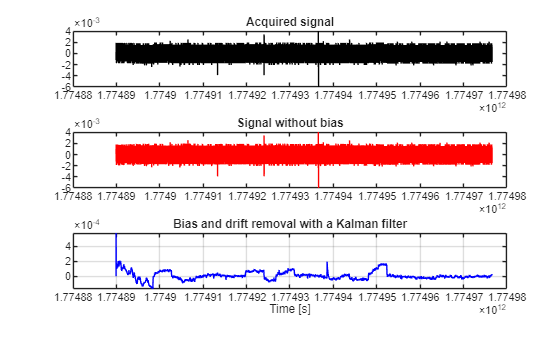

%% Allan deviation with kalman
[allan_var_corrected, ~] = allanvar(omega_corrected,'octave', Fs);
allan_dev_corrected = sqrt(allan_var_corrected);

%% Plot signal
figure(6);
subplot(3,1,1); plot(table_trimmed.timestamp, omega,'k'); title('Acquired signal');
subplot(3,1,2); plot(table_trimmed.timestamp, omega_corrected,'r'); title('Signal without bias');
subplot(3,1,3); plot(table_trimmed.timestamp, b_hat,'b'); title('Estimated bias');
xlabel('Time [s]');
title('Bias and drift removal with a Kalman filter');
grid on;

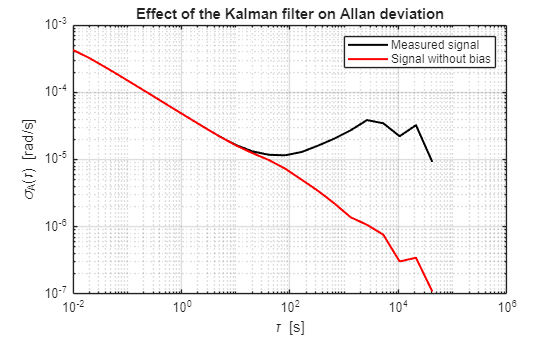

%% Plot Allan deviation
figure(7);
loglog(tau, allan_dev,'k','LineWidth',1.5); hold on;
loglog(tau, allan_dev_corrected,'r','LineWidth',1.5);
xlabel('\tau [s]'); ylabel('\sigma_A(\tau) [rad/s]');
grid on;
legend('Measured signal','Signal without bias');
title('Effect of the Kalman filter on Allan deviation');